clear, clc, close all
% 
load Subjects.mat
subjectName = ["Dog_1", "Dog_2", "Dog_3", "Dog_4"];
patientName = ["Patient_2", "Patient_8"];

% 
rng default
warning off

figSaveDir = "D:/James/research_results/gradCAM_results"

% Load Data of each patient 
leaveOneIndice = [1,2,3,4];
firstSpecifyIdx = 1;
firstTargetSubject = subjectName(leaveOneIndice == firstSpecifyIdx);
firstTargetData = load(sprintf("../Seizure_detection_DTF_graph/%s_DTF_AIC_order", firstTargetSubject));

firstIctal = firstTargetData.ictal2;
firstInterictal = firstTargetData.interictal2;

firstIctal = cellfun(@(x) x{1}, firstIctal, "UniformOutput",false);
firstInterictal = cellfun(@(x) x{1}, firstInterictal, "UniformOutput",false);

secondSpecifyIdx = 2;
secondTargetSubject = subjectName(leaveOneIndice == secondSpecifyIdx);
secondTargetData = load(sprintf("../Seizure_detection_DTF_graph/%s_DTF_AIC_order", secondTargetSubject));

secondIctal = secondTargetData.ictal2;
secondInterictal = secondTargetData.interictal2;

secondIctal = cellfun(@(x) x{1}, secondIctal, "UniformOutput",false);
secondInterictal = cellfun(@(x) x{1}, secondInterictal, "UniformOutput",false);

%
thirdSpecifyIdx = 3;
thirdTargetSubject = subjectName(leaveOneIndice == thirdSpecifyIdx);
thirdTargetData = load(sprintf("../Seizure_detection_DTF_graph/%s_DTF_AIC_order", thirdTargetSubject));

thirdIctal = thirdTargetData.ictal2;
thirdInterictal = thirdTargetData.interictal2;

thirdIctal = cellfun(@(x) x{1}, thirdIctal, "UniformOutput",false);
thirdInterictal = cellfun(@(x) x{1}, thirdInterictal, "UniformOutput",false);

forthSpecifyIdx = 4;
forthTargetSubject = subjectName(leaveOneIndice == forthSpecifyIdx);
forthTargetData = load(sprintf("../Seizure_detection_DTF_graph/%s_DTF_AIC_order", forthTargetSubject));

forthIctal = forthTargetData.ictal2;
forthInterictal = forthTargetData.interictal2;

forthIctal = cellfun(@(x) x{1}, forthIctal, "UniformOutput",false);
forthInterictal = cellfun(@(x) x{1}, forthInterictal, "UniformOutput",false);

patientIdx = 1;
p1TargetSubject = patientName(patientIdx);
p1TargetData = load(sprintf("../Seizure_detection_DTF_graph/%s_DTF_AIC_order", p1TargetSubject));

p1Ictal = p1TargetData.ictal2;
p1Interictal = p1TargetData.interictal2;

p1Ictal = cellfun(@(x) x{1}, p1Ictal, "UniformOutput",false);
p1Interictal = cellfun(@(x) x{1}, p1Interictal, "UniformOutput",false);

patientIdx = 2;
p2TargetSubject = patientName(patientIdx);
p2TargetData = load(sprintf("../Seizure_detection_DTF_graph/%s_DTF_AIC_order", p1TargetSubject));

p2Ictal = p2TargetData.ictal2;
p2Interictal = p2TargetData.interictal2;

p2Ictal = cellfun(@(x) x{1}, p2Ictal, "UniformOutput",false);
p2Interictal = cellfun(@(x) x{1}, p2Interictal, "UniformOutput",false);

clear firstTargetData secondTargetData thirdTargetData forthTargetData p1TargetData p2TargetData

% Reshape
firstIctal = cellfun(@(x) fig2channel(x, 16), firstIctal, "UniformOutput",false);
firstInterictal = cellfun(@(x) fig2channel(x, 16), firstInterictal, "UniformOutput",false);
secondIctal = cellfun(@(x) fig2channel(x, 16), secondIctal, "UniformOutput",false);
secondInterictal = cellfun(@(x) fig2channel(x, 16), secondInterictal, "UniformOutput",false);
thirdIctal = cellfun(@(x) fig2channel(x, 16), thirdIctal, "UniformOutput",false);
thirdInterictal = cellfun(@(x) fig2channel(x, 16), thirdInterictal, "UniformOutput",false);
forthIctal = cellfun(@(x) fig2channel(x, 16), forthIctal, "UniformOutput",false);
forthInterictal = cellfun(@(x) fig2channel(x, 16), forthInterictal, "UniformOutput",false);

p1Ictal = cellfun(@(x) fig2channel(x, 16), p1Ictal, "UniformOutput",false);
p1Interictal = cellfun(@(x) fig2channel(x, 16), p1Interictal, "UniformOutput",false);
p2Ictal = cellfun(@(x) fig2channel(x, 16), p2Ictal, "UniformOutput",false);
p2Interictal = cellfun(@(x) fig2channel(x, 16), p2Interictal, "UniformOutput",false);

% Reshape to 1D vector 

ff = cell2mat(firstIctal);
fInter = cell2mat(firstInterictal);

fs = cell2mat(secondIctal);
fsInter = cell2mat(secondInterictal);

% Reshape to 1D vector 
fthird = cell2mat(thirdIctal);
fthirdInter = cell2mat(thirdInterictal);

fsforth = cell2mat(forthIctal);
fsforthInter = cell2mat(forthInterictal);

% Reshape to 1D vector 
p1Ictal = cell2mat(p1Ictal);
p1Interictal = cell2mat(p1Interictal);

p2Ictal = cell2mat(p2Ictal);
p2Interictal = cell2mat(p2Interictal);

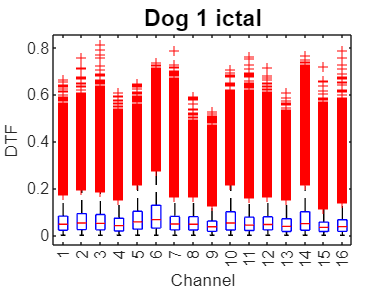

% Boxplot
figure()
boxplot(ff)
xlabel("Channel")
ylabel("DTF")
title("Dog 1 ictal", "FontSize", 14)

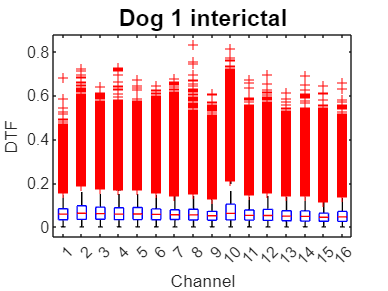


figure()
boxplot(fInter)
xlabel("Channel")
ylabel("DTF")
title("Dog 1 interictal", "FontSize", 14)

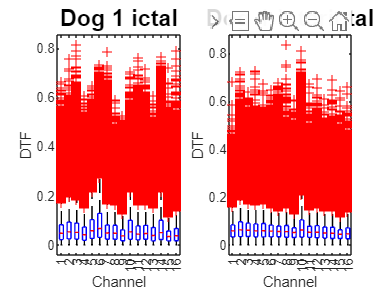


figure()
subplot(1,2,1)
boxplot(ff)
xlabel("Channel")
ylabel("DTF")
title("Dog 1 ictal", "FontSize", 14)

subplot(1,2,2)
boxplot(fInter)
xlabel("Channel")
ylabel("DTF")
title("Dog 1 interictal", "FontSize", 14)

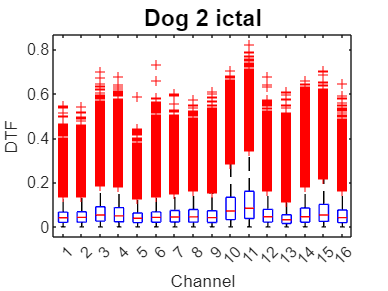

figure()
boxplot(fs)
xlabel("Channel")
ylabel("DTF")
title("Dog 2 ictal", "FontSize", 14)

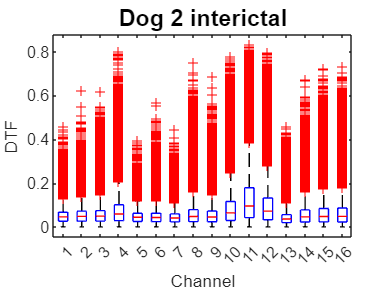


figure()
boxplot(fsInter)
xlabel("Channel")
ylabel("DTF")
title("Dog 2 interictal", "FontSize", 14)

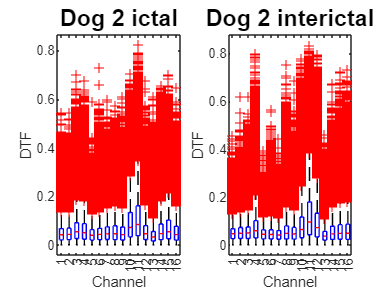


figure()
subplot(1,2,1)
boxplot(fs)
xlabel("Channel")
ylabel("DTF")
title("Dog 2 ictal", "FontSize", 14)

subplot(1,2,2)
boxplot(fsInter)
xlabel("Channel")
ylabel("DTF")
title("Dog 2 interictal", "FontSize", 14)

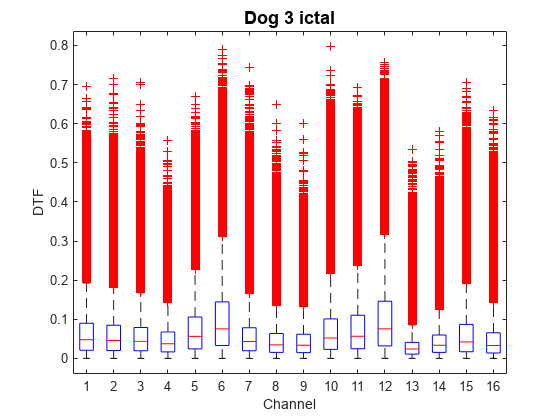

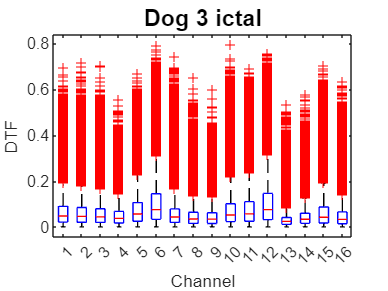

figure()
boxplot(fthird)
xlabel("Channel")
ylabel("DTF")
title("Dog 3 ictal", "FontSize", 14)

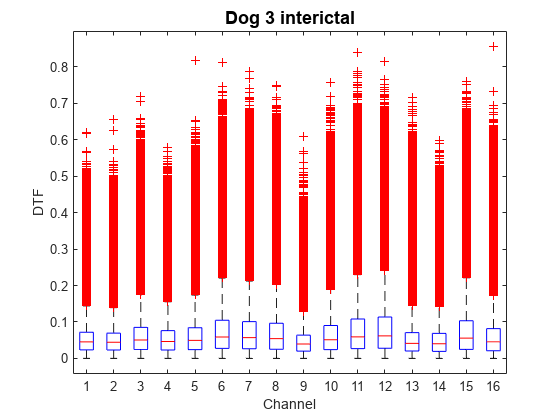


figure()
boxplot(fthirdInter)
xlabel("Channel")
ylabel("DTF")
title("Dog 3 interictal", "FontSize", 14)

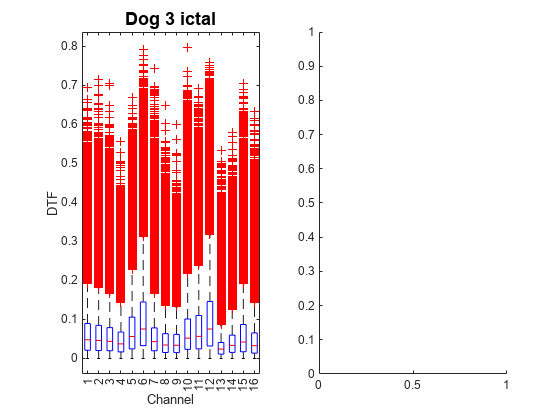

figure()
subplot(1,2,1)
boxplot(fthird)
xlabel("Channel")
ylabel("DTF")
title("Dog 3 ictal", "FontSize", 14)

subplot(1,2,2)

boxplot(fthirdInter)
xlabel("Channel")
ylabel("DTF")
title("Dog 3 interictal", "FontSize", 14)

figure()
boxplot(fsforth)
xlabel("Channel")
ylabel("DTF")
title("Dog 4 ictal", "FontSize", 14)

figure()
boxplot(fsforthInter)
xlabel("Channel")
ylabel("DTF")
title("Dog 4 interictal", "FontSize", 14)

figure()
subplot(1,2,1)
boxplot(fsforth)
xlabel("Channel")
ylabel("DTF")
title("Dog 4 ictal", "FontSize", 14)

subplot(1,2,2)
boxplot(fsforthInter)
xlabel("Channel")
ylabel("DTF")
title("Dog 4 interictal", "FontSize", 14)

figure()
boxplot(p1Ictal)
xlabel("Channel")
ylabel("DTF")
title("Patient 2 ictal", "FontSize", 14)

figure()
boxplot(p1Interictal)
xlabel("Channel")
ylabel("DTF")
title("Patient 2 interictal", "FontSize", 14)

figure()
subplot(1,2,1)
boxplot(p2Ictal)
xlabel("Channel")
ylabel("DTF")
title("Patient 8 ictal", "FontSize", 14)

subplot(1,2,2)
boxplot(p2Interictal)
xlabel("Channel")
ylabel("DTF")
title("Patient 8 interictal", "FontSize", 14)

figure()
boxplot(p2Ictal)
xlabel("Channel")
ylabel("DTF")
title("Patient 8 ictal", "FontSize", 14)

figure()
boxplot(p2Interictal)
xlabel("Channel")
ylabel("DTF")
title("Patient 8 interictal", "FontSize", 14)

function channelDTF = fig2channel(DTF, numChannels)
% 將 2D DTF 拆分成以 channels 數對應的 DTF values
st = 1:numChannels;
channelDTF = zeros(size(DTF, 1)*numChannels, numChannels);
for i = 1:numChannels 
    channelDTF(:,i) = reshape(DTF(:,st), [], 1);
    st = st + numChannels;
end
end